d = 215 %mm

d = 215

data = importdata("data\Experiments.xlsx")

data = struct with fields:
        data: [60×3 double]
    textdata: {32×4 cell}


v = d./data.data

v =     6.8734    7.1098    6.3403
    7.4472    7.9748    6.5769
    7.2956    6.0615    5.0660
    7.7422    6.2031    5.2477
    7.4575    6.6543    5.1264
    7.1547    7.3179    5.8376
    7.1074    7.2269    5.5990
    7.0216    5.8936    5.8250
    7.3379    6.3950    6.0632
    7.1357    6.0529    5.5327


deg0_with = data.data(1:30,1);
deg5_with = data.data(1:30,2);
deg10_with = data.data(1:30,3);
deg0_without = data.data(31:60,1);
deg5_without = data.data(31:60,2);
deg10_without = data.data(31:60,3);
deg0_with_v = d./deg0_with;
deg5_with_v = d./deg5_with;
deg10_with_v = d./deg10_with;
deg0_without_v = d./deg0_without;
deg5_without_v = d./deg5_without;
deg10_without_v = d./deg10_without;

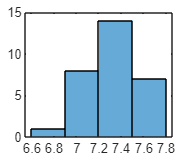

histogram(deg0_with_v)

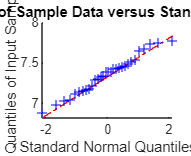

qqplot(deg0_with_v)

mean(deg0_with_v)

ans = 7.3496

var(deg0_with_v)/sqrt(30)

ans = 0.0100

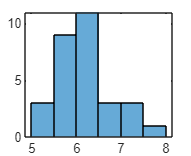

histogram(deg5_with_v)

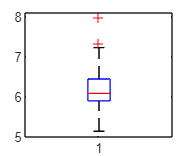

boxplot(deg5_with_v)

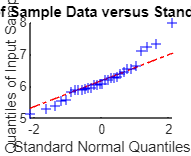

qqplot(deg5_with_v)

mean(deg5_with_v)

ans = 6.2009

var(deg5_with_v)/sqrt(30)

ans = 0.0690

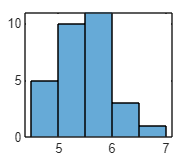

histogram(deg10_with_v)

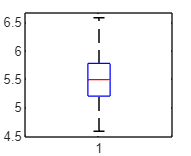

boxplot(deg10_with_v)

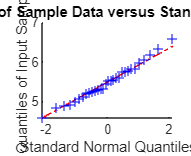

qqplot(deg10_with_v)

mean(deg10_with_v)

ans = 5.4890

var(deg10_with_v)/sqrt(30)

ans = 0.0393

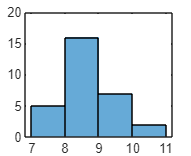

histogram(deg0_without_v)

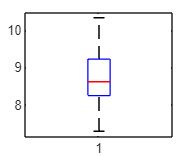

boxplot(deg0_without_v)

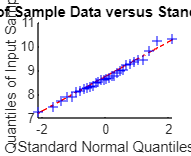

qqplot(deg0_without_v)

mean(deg0_without_v)

ans = 8.6911

var(deg0_without_v)/sqrt(30)

ans = 0.0991

[h,p,ci,std]=ttest(deg0_without_v)

h = 1

p = 6.8031e-33

ci =     8.4159
    8.9663


std = struct with fields:
    tstat: 64.6006
       df: 29
       sd: 0.7369


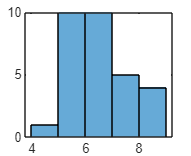

histogram(deg5_without_v)

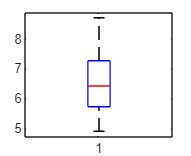

boxplot(deg5_without_v)

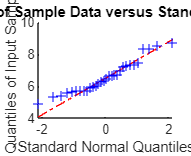

qqplot(deg5_without_v)

mean(deg5_without_v)

ans = 6.5718

var(deg5_without_v)/sqrt(30)

ans = 0.1860

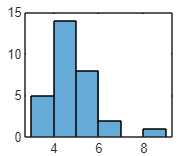

histogram(deg10_without_v)

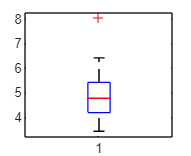

boxplot(deg10_without_v)

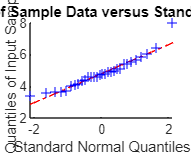

qqplot(deg10_without_v)

mean(deg10_without_v)

ans = 4.8570

var(deg10_without_v)/sqrt(30)

ans = 0.1702

[~,tbl,stats] = anova2(v,30,"on")

tbl = 6×6 cell array
    {'Source'     }    {'SS'      }    {'df' }    {'MS'      }    {'F'       }    {'Prob>F'    }
    {'Columns'    }    {[244.9928]}    {[  2]}    {[122.4964]}    {[233.9525]}    {[4.7624e-50]}
    {'Rows'       }    {[  5.8365]}    {[  1]}    {[  5.8365]}    {[ 11.1469]}    {[    0.0010]}
    {'Interaction'}    {[ 29.2123]}    {[  2]}    {[ 14.6062]}    {[ 27.8959]}    {[3.1022e-11]}
    {'Error'      }    {[ 91.1056]}    {[174]}    {[  0.5236]}    {0×0 double}    {0×0 double  }
    {'Total'      }    {[371.1472]}    {[179]}    {0×0 double}    {0×0 double}    {0×0 double  }


stats = struct with fields:
      source: 'anova2'
     sigmasq: 0.5236
    colmeans: [8.0204 6.3864 5.1730]
        coln: 60
    rowmeans: [6.3465 6.7066]
        rown: 90
       inter: 1
        pval: 3.1022e-11
          df: 174


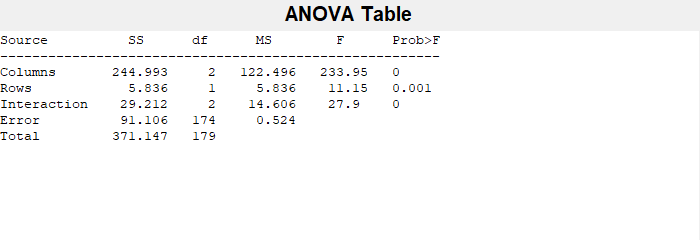

Note: Your model includes an interaction term that is significant at the level 
you specified. Testing main effects under these conditions is questionable.


c1 = multcompare(stats,"CriticalValueType","hsd");

tbl1 = array2table(c1,"VariableNames", ...
    ["Group A","Group B","Lower Limit","A-B","Upper Limit","P-value"])

tbl1 = 3×6 table
    Group A    Group B    Lower Limit     A-B      Upper Limit     P-value  
    _______    _______    ___________    ______    ___________    __________

       1          2          1.3244       1.634      1.9436                0
       1          3          2.5377      2.8474       3.157                0
       2          3         0.90372      1.2134       1.523       3.3419e-20


Note: Your model includes an interaction term that is significant at the level 
you specified. Testing main effects under these conditions is questionable.


c2 = multcompare(stats,"estimate","row","CriticalValueType","hsd");

tbl2 = array2table(c2,"VariableNames", ...
    ["Group A","Group B","Lower Limit","A-B","Upper Limit","P-value"])

tbl2 = 1×6 table
    Group A    Group B    Lower Limit      A-B       Upper Limit     P-value  
    _______    _______    ___________    ________    ___________    __________

       1          2        -0.57155      -0.36014     -0.14872      0.00084173


data = [deg0_without_v, deg0_with_v, deg5_without_v, deg5_with_v, deg10_without_v, deg10_with_v];  % Cell array holds different datasets
aov = anova(data)

aov = 1-way anova, constrained (Type III) sums of squares.

Y ~ 1 + Factor1

               SumOfSquares    DF     MeanSquares      F         pValue  
               ____________    ___    ___________    ______    __________

    Factor1       280.04         5      56.008       106.97    3.4974e-51
    Error         91.106       174      0.5236                           
    Total         371.15       179                                       


  Properties, Methods



c3 = multcompare(aov,"CriticalValueType","hsd");
tbl1 = array2table(c3,"VariableNames", ...
    ["Group A","Group B","Lower Limit","A-B","Upper Limit","P-value"])

tbl1 = 15×6 table
    Group A    Group B     Lower Limit              A-B                Upper Limit         P-value  
    Group1     Group2     MeanDifference    MeanDifferenceLower    MeanDifferenceUpper      pValue  
    _______    _______    ______________    ___________________    ___________________    __________

      1          2             1.3415             0.80905                  1.8739          8.373e-12
      1          3             2.1193              1.5868                  2.6517                  0
      1          4             2.4902              1.9578                  3.0226                  0
      1          5             3.8341              3.3017            


% Organize data in a cell array for easy access
data = {deg0_without_v, deg0_with_v, deg5_without_v, deg5_with_v, deg10_without_v, deg10_with_v};  % Cell array holds different datasets

figure;
hold on;  % Allows plotting all data on one figure

data_plot(1,deg0_without_v,'r')
data_plot(2,deg0_with_v,'b')
data_plot(4,deg5_without_v,'r')
data_plot(5,deg5_with_v,'b')
data_plot(7,deg10_without_v,'r')
data_plot(8,deg10_with_v,'b')

x0=10;
y0=10;
width=550;
height=450;
set(gcf,'position',[x0,y0,width,height]);

% Set axis limits and labels
ylim([3.3 10.5]);  % Adjust this based on your data
xlim([0 9]);  % To fit the 3 groups
xticks([1.5, 4.5, 7.5]);  % x-axis tick positions
xticklabels({'0$^{\circ}$','5$^{\circ}$','10$^{\circ}$'});  % Labels
set(gca, 'TickLabelInterpreter', 'latex')

% Add plot labels
xlabel('Angle','Interpreter','latex');
ylabel('Speed $\left[\frac{\mathrm{mm}}{\mathrm{s}}\right]$','Interpreter','latex');
title('Speed VS. Angle','Interpreter','latex');
lgnd= legend('Without skin','','With skin','Interpreter','latex','location','southwest')

lgnd =   Legend (Without skin, With skin) with properties:

         String: {'Without skin'  'With skin'}
       Location: 'southwest'
    Orientation: 'vertical'
       FontSize: 9
       Position: [0.1487 0.1338 0.2188 0.0739]
          Units: 'normalized'

  Show all properties


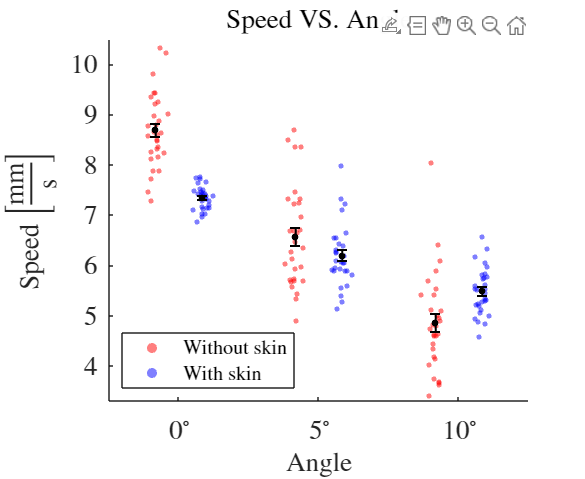

fontsize(16,'points')
fontsize(lgnd,12,'points')
hold off;